load fisheriris
N = size(meas,1);

Partition the data into training and test sets. Hold out 10% of the data for testing.

rng(1); % For reproducibility
cvp = cvpartition(N,'Holdout',0.1);
idxTrn = training(cvp); % Training set indices
idxTest = test(cvp);    % Test set indices

Create an indicator variable for "species is 'virginica'".

for i = 1:length(species)
     is_virginicac{i} = strcmp(species{i}, 'virginica');
end 

is_virginica = transpose(cell2mat(is_virginicac));

Store the training data in a table.

tblTrn = array2table(meas(idxTrn,:));
tblTrn.Y = is_virginica(idxTrn);

Train a classification ensemble using AdaBoostM1 and the training set. Specify tree stumps as the weak learners.

t = templateTree('MaxNumSplits',1);
Mdl = fitcensemble(tblTrn,'Y','Method','AdaBoostM1','Learners',t);

Predict labels for the test set. You trained model using a table of data, but you can predict labels using a matrix.

[labels, scores] = predict(Mdl,meas(idxTest,:));

Construct a confusion matrix for the test set.

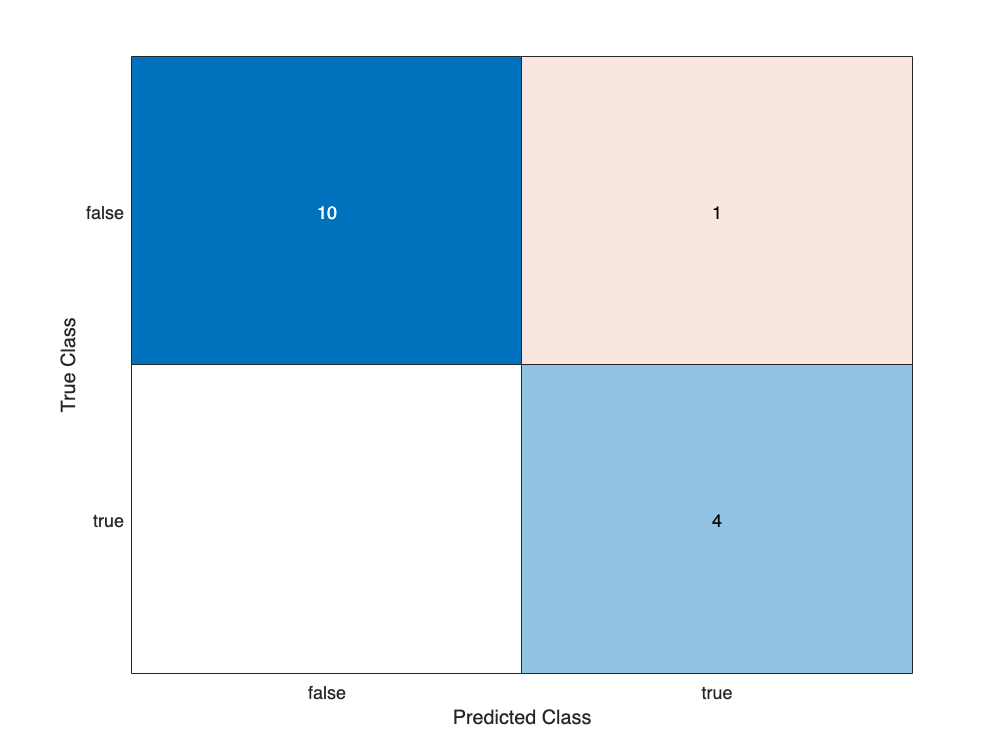

confusionchart(is_setosa(idxTest),labels)

transpose(find(idxTest == 1))

ans =      3    13    16    23    25    29    43    44    61    82    84   109   112   122   127
